# Ficudals

Ndicom = 112;

global dis_pos_width;
global dis_neg_width;
global dis_pos_depth;
global dis_neg_depth;
global dis_pos_height;
global dis_neg_height;

global dic_pos_width;
global dic_neg_width;
global dic_pos_depth;
global dic_neg_depth;
global dic_pos_height;
global dic_neg_height;

skin1 = 'r';
skin2 = [0.9290 0.6940 0.1250];
skull_color_2=[0 0 0.7];
skull_color_1=[1 1 1];
skul_height=3;

N=112;
height_img= round(skul_height/N,2);


## Load


[V,F,UV,TF,N,NF] = readOBJ('Human_body.obj');

fv = stlread('Crani.stl');


## Ficudals coordinates


% Skull is centered on (0,0,0)
% Display coordinates: Set by Skull's container box (mm)

dis_pos_width = max(fv.vertices(:,1));
dis_neg_width = min(fv.vertices(:,1));

dis_pos_depth = max(fv.vertices(:,2));
dis_neg_depth = min(fv.vertices(:,2));

dis_pos_height = max(fv.vertices(:,3));
dis_neg_height = min(fv.vertices(:,3));

%Dicom coordinates: Get Skull's container box in dicom images (mm)
%Obtained from slice 62, the biggest size.

dic_pos_width = 204;
dic_neg_width = 42;

dic_pos_depth = 234;
dic_neg_depth = 26;

dic_pos_height = Ndicom;
dic_neg_height = 1;


%ficudals x,y in dicom coordinates. Get from images.
%ficudal z, in dicom coord, corresponds with num of slice

dicom_fic_1 = [121,210,19];
dicom_fic_2 = [183,210,48];
dicom_fic_3 = [70,210,81];

%Convert ficudals dicom coordinates to display coord

display_fic_1=[X_dicom2display(dicom_fic_1(1)),...
    Y_dicom2display(dicom_fic_1(2)),...
    Z_dicom2display(dicom_fic_1(3))];

display_fic_2=[X_dicom2display(dicom_fic_2(1)),...
    Y_dicom2display(dicom_fic_2(2)),...
    Z_dicom2display(dicom_fic_2(3))];

display_fic_3=[X_dicom2display(dicom_fic_3(1)),...
    Y_dicom2display(dicom_fic_3(2)),...
    Z_dicom2display(dicom_fic_3(3))];


## Transforms

% Resize
fv.vertices = fv.vertices*0.1;
display_fic_1 = display_fic_1*0.1;
display_fic_2 = display_fic_2*0.1;
display_fic_3 = display_fic_3*0.1;
V = V*4;

%Rotate
theta=pi/2;
R=rotx(theta);
fv.vertices = fv.vertices*R;
display_fic_1 = display_fic_1*R;
display_fic_2 = display_fic_2*R;
display_fic_3 = display_fic_3*R;

% %Translate
T= transl(0,2,0);
for i=1:size(V,1)
    for j=1:size(V,2)
            aux = [V(i,:) 1]';
            P = T*aux;
            V(i,:) = P(1:3);
            V(i,:);
    end
end



## Display

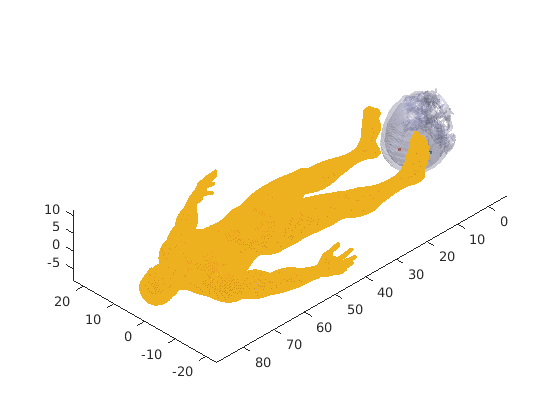


hold on
p = patch('faces',F,'vertices',V,'FaceColor',skin1,'EdgeColor',skin2);
hold on

patch(fv,'FaceColor',       [0.8 0.8 1.0], ...
         'EdgeColor',       'none',        ...
         'FaceLighting',    'gouraud',     ...
         'AmbientStrength', 0.15);

% Add a camera light, and tone down the specular highlighting
camlight('headlight');
material('shiny');
alpha 0.2

% Fix the axes scaling, and set a nice view angle
axis('image');
view([-135 35]);
hold on
plot3(display_fic_1(1),display_fic_1(2),display_fic_1(3),'.');
hold on
plot3(display_fic_2(1),display_fic_2(2),display_fic_2(3),'.');
hold on
plot3(display_fic_3(1),display_fic_3(2),display_fic_3(3),'.');

function X = X_dicom2display(xdicom)
    
    global dis_pos_width;
    global dis_neg_width;
    global dic_pos_width;
    global dic_neg_width;
    
    a = (xdicom-dic_neg_width);
    b = (dic_pos_width-dic_neg_width);
    c = -(dis_neg_width);
    d = (dis_pos_width-dis_neg_width);
    
    Xdec = ((a*d)-(b*c))/(b);    
    X = round(Xdec);

end

function Y = Y_dicom2display(ydicom)

    global dis_pos_depth;
    global dis_neg_depth;
    global dic_pos_depth;
    global dic_neg_depth;
    
    a = (ydicom-dic_neg_depth);
    b = (dic_pos_depth-dic_neg_depth);
    c = -(dis_neg_depth);
    d = (dis_pos_depth-dis_neg_depth);
    
    Ydec = ((a*d)-(b*c))/(b);
    Y = round(Ydec);

end

function Z = Z_dicom2display(zdicom)

    global dis_pos_height;
    global dis_neg_height;
    global dic_pos_height;
    global dic_neg_height;
    
    a = (zdicom-dic_neg_height);
    b = (dic_pos_height-dic_neg_height);
    c = -(dis_neg_height);
    d = (dis_pos_height-dis_neg_height);
    
    Zdec = ((a*d)-(b*c))/(b);    
    Z = round(Zdec);

end


